%Created by : Juan Briones
%Student Number A00825852
% Calculo para casos generales, entrada N, M

%Inputs - x and y vectors

x=[-3, -2, -1, 0, 1, 2, 3];
y=[7.5, 3, 0.5, 1, 3, 6, 14];

%Process - Use the corresponding regression formulas for
%the polynomial regression

A = [];
B = [];

n = length(x)

n = 7

nArray = 3

nArray = 3


% f: retorna la suma de los elementos del array a una potnecia dada
f = @(b, p) sum(b.^p); 

% g: retorna la suma pero de 2 arrays y uno de ellos elevados a una
% potencia, donde b es el elevado a la potencia p
g = @(b, c, p) sum(c.*(b.^p)); 

for i=1:nArray
    for j=1:nArray
        if i==1 && j==1
            A(i, j) = n;
        else 
            A(i, j) = f(x, (i-1)+(j-1));
        end
    end
end

for i=1:nArray
    if i==1
        B(i, 1) = f(y, 1);
    else
        B(i, 1) = g(x, y, (i-1));
    end
end

R = inv(A)*B

R =     0.5714
    1.0000
    1.1071



%Output - display results
% a0 a1 a2

a0 = R(1, 1);
a1 = R(2, 1);
a2 = R(3, 1);

disp("a0 = "+a0)

a0 = 0.57143


disp("a1 = "+a1)

a1 = 1


disp("a2 = "+a2)

a2 = 1.1071



disp("y="+a0+" + "+a1+"x + "+a2+"x^2")

y=0.57143 + 1x + 1.1071x^2


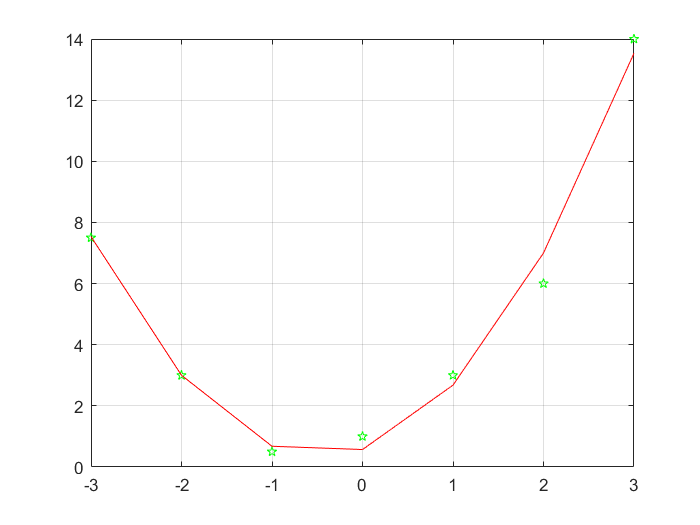

h = @(x) a0 + a1*x + a2 * power(x, 2); 

figure
plot(x, y, 'pg')
hold on
plot(x, h(x), '-r')
hold off
grid